# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

## Calculate the noise equivalent sigma zero 

$\textrm{NESZ}=\frac{8\pi \;\lambda \;r^3 v\;k\;T_{0\;} F\;L}{P_{\textrm{avg}} \;A_e^2 {\;\delta }_r }$    Equation (2.27)

% Clear the workspace
clear

% Range resolution (m)
range_resolution = [1, 5, 10];

% Average transmitted power (W)
average_power = 800;

% Antenna effective aperture (m^2)
effective_aperture = 3.5;

% Operating frequency (Hz)
operating_frequency = 900e6;

% Slant range (m)
slant_range = 200e3;

% System temperature (K)
system_temperature = 290;

% Noise figure (dB)
noise_figure = 4;

% Losses (dB)
losses = 8;

% Velocity (m/s)
velocity = linspace(10, 250, 1e3);

% Calculate the noise equivalent sigma zero
for i = 1:length(range_resolution)
    nesz(i,:) = stripmap_nesz(average_power, effective_aperture, range_resolution(i), ...
        operating_frequency, slant_range, velocity, system_temperature, noise_figure, losses);
end

## Plot the results

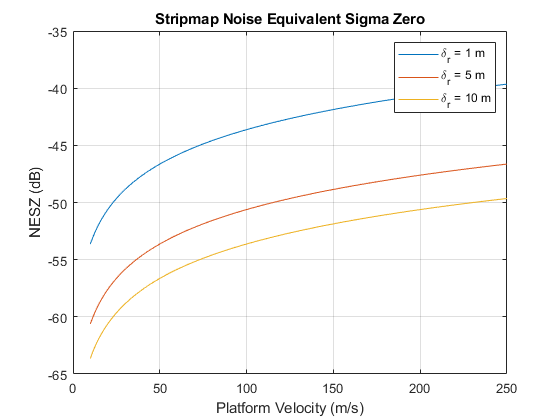

figure;
plot(velocity, db(nesz));
xlabel('Platform Velocity (m/s)')
ylabel('NESZ (dB)');
title('Stripmap Noise Equivalent Sigma Zero')
legend('\delta_r = 1 m', '\delta_r = 5 m', '\delta_r = 10 m')
grid on